# Vergleich der Gauß-Quadratur und summierten Simpsonregel

Wir untersuchen die Gauß-Quadratur mit 4 Stützstellen ($m=3$)  (ohne Wiederholung)  und die summierte Simpsonregel mit $n=16$ Wiederholungen, zur Annäherung eines Integrals $I=\int_0^1 f(x)\, dx$, also

    $G:= \sum_{j=0}^3  c_j f(x_j)$,

mit Koeffizienten und Stützstellen der Gauß-Methode (siehe Buch),  und

    $S(h)=\frac{h}{6}\Big[ f(0) +4 f\big(\frac{t_1}{2}\big)+ 2f(t_1)+4f\big(\frac{t_1+t_2}{2}\big) + 2f(t_2) +\ldots+2f(t_{n-1})+ 4 f\big(\frac{t_{n-1}+t_n}{2}\big)+  f(1)\Big]$, 

mit $t_j=jh$, $h=1/n,~~n:=16.$

Als Beispiele betrachten wir:

    1.   $f(x)=0.25\pi^2 x\cos(0.5 \pi x)+0.5\pi e^{0.5\pi x}$    (Beispiel Buch umskaliert auf $[0,1]$)

    2.   $f(x)= x e^x$       (glatte Funktion)

    3.  $f(x)= \sqrt{x}$        (nicht glatt an der Stelle $x=0$)

    4.  $f(x)= \sqrt{|x-\frac13|}$   (nicht glatt an der Stelle $x=\frac{1}{3}$)

Für diese Bespiele kann analytisch der exakte Wert des Integrals $I$ berechnet werden.

Durch Angabe von **choice** $\in \{1,2,3,4\}$ wird eins dieser Bespiele gewählt. 

choice=1

choice = 1

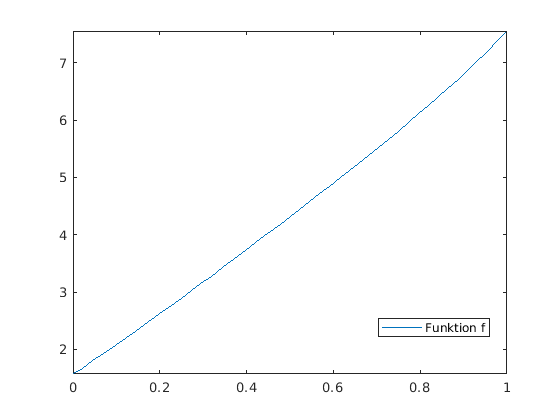

[f,Iexakt]= Beispiel(choice);
fplot(f,[0 1]);
legend('Funktion f', 'Location','best');

Die Gauß-Quadratur $G$ und der Fehler $|G-I|$ werden berechnet und gezeigt.

Für $n=16$ werden die Simpsonsumme $S(1/n)$ und der Fehler $|S(1/n)-I|$ berechnet und gezeigt.

# Aktivität:

Sie können den Parameter** choice** variieren und ggf. eigene Beispiele hinzufügen. Beobachten Sie die Fehler der beiden Methoden und beurteilen Sie die Effizienz der beiden Methoden.

% zunaechst Gauss-Quadratur:
z1= sqrt(3/7 + 2/7*sqrt(6/5));  z2= sqrt(3/7 - 2/7*sqrt(6/5));
xGauss= [ (-z1+1)/2; (z1+1)/2; (-z2+1)/2; (z2+1)/2 ]; % Stuetzstellen
c1= (18-sqrt(30))/72;  c2= (18+sqrt(30))/72;
cGauss= [ c1; c1; c2; c2 ]; % Gewichte
Gauss=0;
for i=1:4
    Gauss= Gauss + cGauss(i)*f(xGauss(i));
end
fprintf('\nErgebnis der Gauß-Quadratur mit 4 f-Auswertungen:\n');


Ergebnis der Gauß-Quadratur mit 4 f-Auswertungen:


format long;
GaussResultat= Gauss

GaussResultat =    4.381273435207490


format short;
FehlerGauss= abs(Gauss - Iexakt) 

FehlerGauss = 2.7255e-07


% nun Quadratur mit der summierten Simpsonregel:
n=16;
h=1/n;
S= 1/6*(f(0) + f(1)) + 2/3*f(0.5*h);
for i=1:n-1
    S= S + 1/3*f(i*h) + 2/3*f((i+0.5)*h);
end
disp('----------------');

----------------


fprintf('\nErgebnis der summierten Simpsonregel mit %d f-Auswertungen:\n',2*n+1);


Ergebnis der summierten Simpsonregel mit 33 f-Auswertungen:


format long;
SimpsonResultat= h*S

SimpsonResultat =    4.381273978130053


format short;
FehlerSimpson= abs(SimpsonResultat - Iexakt)

FehlerSimpson = 2.7037e-07

function [f,Iexakt]= Beispiel(bsp)
switch bsp
    case 1
        f= @(x) 0.25*pi^2*x.*cos(0.5*pi.*x) + 0.5*pi*exp(0.5*pi.*x);
        Iexakt= pi/2 + exp(0.5*pi) - 2;
    case 2
        f= @(x) x.*exp(x);
        Iexakt= 1;
    case 3
        f= @(x) sqrt(x);
        Iexakt= 2/3;
    case 4
        f= @(x) sqrt( abs(x - 1/3));
        Iexakt= 2/27*sqrt(3) + 4/27*sqrt(6);
end

end